# Simulating a Gaussian Process

To simulate a Gaussian process we use a technique called circulant embedding.

This technique provides two realisations every time a generation is performed, so a second optionally time series will always be generated when using the simulation method.

We again return to the wave example discussed previously. Define the model

sdf = @spectralFitting.genJONSWAPsdf;
theta = [0.7;0.7;3.3;4];
lb = [0;0;1;1];
ub = Inf(4,1);
waveSpecModel = spectralFitting.SpectralModel(sdf,theta,lb,ub);

We then specify the desired number of observations $N$ to be

N = 2048;

and the sampling interval $\Delta$ as

Delta = 1/2;

Meaning we will simulate a series that lasts for $T=N/\Delta$.

Simulation is then performed by using

[gp1,gp2] = waveSpecModel.simulateGaussianProcess(N,Delta);

This provides two column vectors of length $N$, sampled at times

tau = 0:Delta:(N-1)*Delta;

Visually

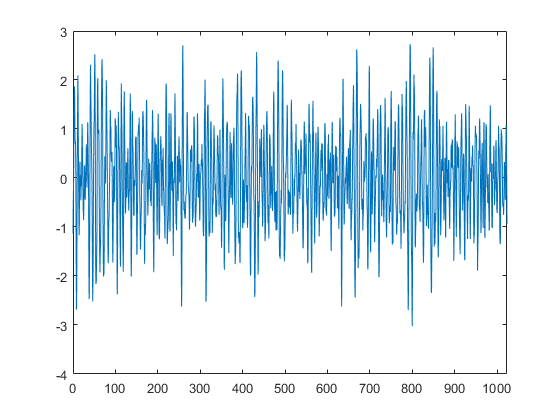

plot(tau,gp1);
xlim([0,(N-1)*Delta]);

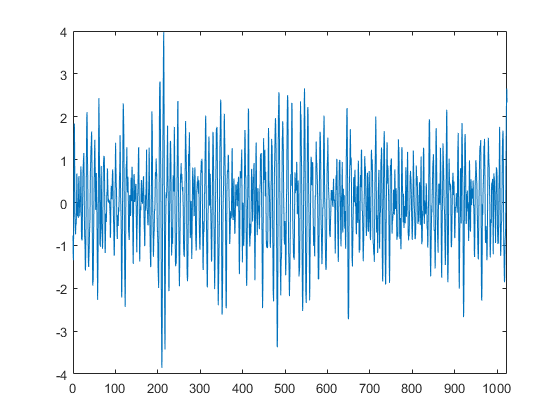

plot(tau,gp2)
xlim([0,(N-1)*Delta]);